# Lab 2 Algorithms' Evaluation

## Reading the image

Choose the image from the drop down menu then run the cell below it.

userInput = "rdb005ll"

userInput = "rdb005ll"

switch userInput
    case 'rdb005ll'
        i=1;
    case 'rdb023ll'
        i=2;
    case 'rdb025ll'
        i=3;
    case 'rdb028rl'
        i=4;
    otherwise
        disp('Wrong Chice');
end

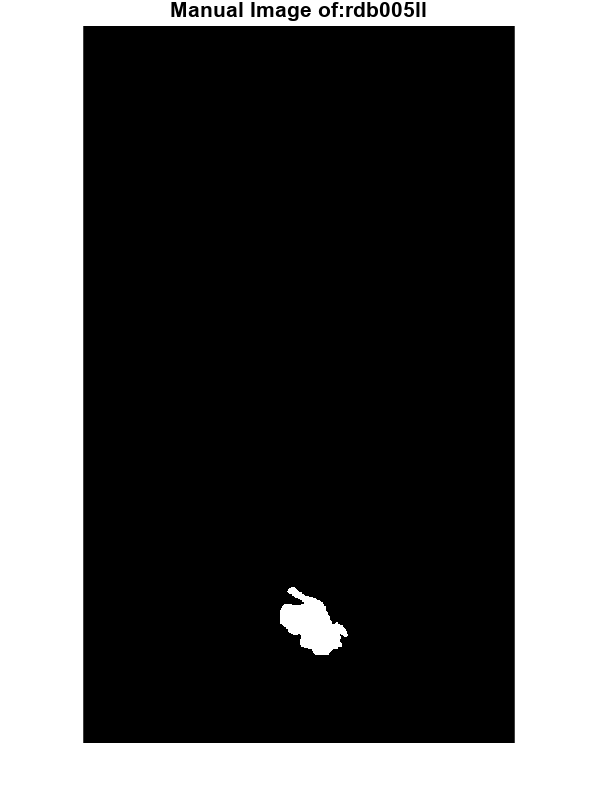

%% This is to choose on of the Ground Truth images.
filelist = dir('database\manual\*.tif');
GroundTruth = append('database\manual\',filelist(i).name);
GroundTruth = imread(GroundTruth);
imshow(GroundTruth);
title(strcat('Manual Image of: ',userInput), 'fontsize', 16)

## Algorithms Loop

Run the cells below after completing the functions.

This part will loop over the 6 segmentations of the image to calculate their ROC curves at different thresholds.

% Define color list for plot
colorlist = {'r', 'g', 'b', 'm', 'y', 'c'};
% Intialize the Area, best threshold, Jaccard and Dice cofficients.
H_Dist = zeros(6,1);
Area = zeros(6,1);
best_tr = zeros(1,6);
Jaccard = zeros(1,6);
Dice = zeros(1,6);
Jaccard1 = zeros(1,6);
Dice1 = zeros(1,6);

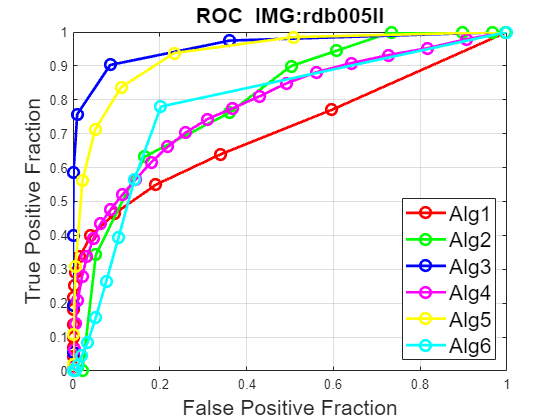

figure
for K = 1: 6
    %% Set path of databases
    Alg1 = imread(append('database\alg', num2str(K), '\', userInput, '.tif'));

    %% Set threshold from 0 to 255 with step 10
    Low = 0;
    High = 255;
    Step = 10;
    Thresholds = Low: Step: High; % Range
    
    %% Get Confusion Matrix
    [TP, TN, FP, FN, TPR, FPR] = Confusion(Alg1, GroundTruth, Thresholds); 
    
    %% Sensitivity and Specificity
    [Sensitivity, Specificity] = SensitivityandSpecificity(TP, FN, FP, TN);

    %% Jaccard Indices and Dice coefficients
    [J_Index, D_Index] = JaccardandDice(FP, TP, FN);

    %% Normalize Values
    FP_R = max(FPR) - min(FPR);
    TP_R = max(TPR) - min(TPR);
    if(TP_R~=0)
       TPR = (TPR - min(TPR))/TP_R;
    end
    if(FP_R~=0)
       FPR = (FPR - min(FPR))/ FP_R;
    end

    %% This is to find the best threshold by using the Euclidan distance
    [minDist] = findbestthreshold(TPR, FPR);
    
    if(length(minDist) > 1)
       best_tr(K)= Thresholds(minDist(1));
    else
       best_tr(K) = Thresholds(minDist);
    end
    
    %% Find the Jaccard and Dice for the best threshold    
    Jaccard(K) = J_Index(minDist(1));
    Dice(K) = D_Index(minDist(1));

    %% Calculate the area under the curve using trapz
    [A] = findarea(TPR, FPR);
    Area(K,1) = A;
    
    %% Hausdorff Distance (HD)
    T = best_tr(K);
    A = GroundTruth;
    B = Alg1;
    B(B>T) = 255;
    B(B<=T) = 0;
    H_Dist(K)= Hausdorff(A, B);

    %% Plot ROC Curve
    legend_str{K} = strcat('Alg', num2str(K));
    plot(FPR,TPR, '-mo', 'MarkerSize',3, 'Color', colorlist{K}, 'linewidth', 2, 'MarkerSize', 8);
    legend(legend_str, 'location', 'SouthEast', 'fontsize', 16);
    grid on;
    hold on;
    xlabel('False Positive Fraction', 'fontsize', 16)
    ylabel('True Positive Fraction', 'fontsize', 16)
    title(strcat('ROC  IMG: ',userInput), 'fontsize', 16)
end
hold off

Area

Area =     0.7122
    0.8002
    0.9587
    0.7888
    0.9340
    0.7862


Jaccard

Jaccard =      0     0     0     0     0     0


Dice

Dice =      0     0     0     0     0     0


H_Dist

H_Dist =     9.4868
    9.4868
    9.4868
    9.4868
    9.4868
    9.4868


## Find the Best Algorithm

Print out the best algorithm based on the areas.

best_curve = find(Area == max(Area));
disp(['Best Algorithm is Alg' num2str(best_curve)]);

Best Algorithm is Alg3
